# Exercise: Comparison of CMG Steering Laws

The pitch axis slew maneuver from the previous exercises shall now be performed with a 4-CMG pyramid array:

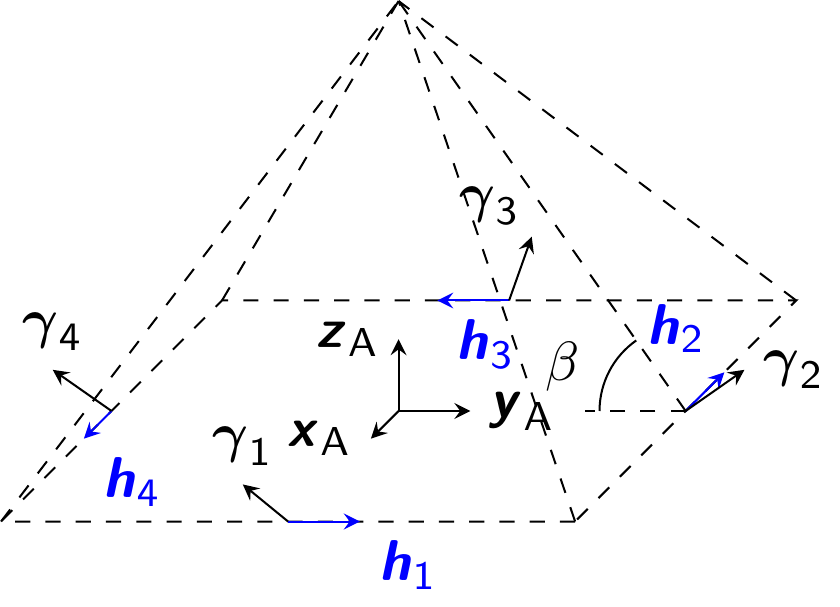

The CMGs' angular momenta $h_k \left(\delta \right)$ and Jacobian $C\left(\delta \right)$ are given by:


$$h_1(\delta_1) = h_{\mathrm{fw}}\,\left(\begin{array}{c}  -\cos\beta\,\sin\delta_1  \\ \cos\delta_1  \\  \sin\beta\,\sin\delta_1  \end{array}\right)
\qquad
h_2(\delta_2) = h_{\mathrm{fw}}\,\left(\begin{array}{c}  -\cos\delta_2  \\ -\cos\beta\,\sin\delta_2  \\  \sin\beta\,\sin\delta_2  \end{array}\right)
\\
h_3(\delta_3) = h_{\mathrm{fw}}\,\left(\begin{array}{c}  \cos\beta\,\sin\delta_3  \\ -\cos\delta_3  \\  \sin\beta\,\sin\delta_3  \end{array}\right)
\qquad
h_4(\delta_4) = h_{\mathrm{fw}}\,\left(\begin{array}{c}  \cos\delta_4  \\ \cos\beta\,\sin\delta_4  \\  \sin\beta\,\sin\delta_4  \end{array}\right)$$



$$C(\delta) = h_{\mathrm{fw}}\,\left[\begin{array}{cccc}
-\cos\beta\,\cos\delta_1  &  \sin\delta_2  & \cos\beta\,\cos\delta_3  &  -\sin\delta_4  \\
-\sin\delta_1  &  -\cos\beta\,\cos\delta_2  &  \sin\delta_3  &  \cos\beta\,\cos\delta_4  \\
\sin\beta\,\cos\delta_1  &  \sin\beta\,\cos\delta_2  &  \sin\beta\,\cos\delta_3  &  \sin\beta\,\cos\delta_4
\end{array}\right]$$


Assume that every CMG has a flywheel angular momentum of $h_{\textrm{fw}} =15\;\textrm{Nms}$ and a maximum gimbal rate of $\dot{\delta}_{\max}=3\,\mathrm{rad/s}$. The pyramid's skew angle shall be $\beta=54.73\degree$. The spacecraft's moment of inertia around the pitch axis is 800 kgm² and the slew maneuver shall follow a bang-(coast-)bang torque profile with a maximum torque of 20 Nm and a maximum angular rate of 3 deg/s.

Note: Assume that the pitch axis is a principal axis, hence we can neglect the gyric torque $\omega \times J\omega$. Also, for sake of simplicity, we will ignore the gyric torque $\omega \times h_{\textrm{CMG}}$ from the CMG array angular momentum in case of undesired torques around the x- or z-axis.

## Define Parameters

% Clean up
clc
clear
close all
addpath('auxFcts/');

% Spacecraft Parameters
satMoi = 800; % [kg m^2]
satTrqMax = 15;  % [Nm]
satAngRateMax = 3 * pi/180; % [rad/s]

% Desired Slew Angle
slewAngle = 30 * pi/180;  % [rad]

% CMG Parameters
cmgFwAngMom = 15; % [Nms]
cmgSkewAngle = 54.73 * pi/180;  % [rad]
cmgMaxGimbalRate = 3; % [rad/s]

The initial gimbal angle configuration is a relevant parameter. We will try the configuration in the figure ($\delta =0$) and $\delta = k\,\left( 1 \:,\: -1 \:,\: 1 \:,\: -1 \right)^{\top}$, which all yield an initial CMG array angular momentum of zero:

cmgGimbalAngles0 = zeros(4,1);  % [rad]
% cmgGimbalAngles0 = pi/3*[1; -1; 1; -1];  % [rad]

% Steering Law Parameters
gsrPars.a = 0.01;
gsrPars.b = sqrt(10);
gsrPars.omega = 0.5*pi;
gsrPars.phi1 = 0;
gsrPars.phi2 = pi/2;
gsrPars.phi3 = pi;
gsrPars.e0 = 0.01;

% Simulation Parameters
dt = 0.05;  % [s] 20Hz simulation frequency
tEnd = 20;  % [s]
tStartSlew = 5; % [s] Start slew at t=5s

## Compute Slew Guidance Profile

satAngMomMax = satMoi*satAngRateMax;
Ka = roundn(satAngMomMax/satTrqMax,-1); % [s] round Ka to multiple of simulation step size

% Check that slew is rate-limited:
isSlewRateLimited = (slewAngle >= satAngRateMax*Ka);
if ~isSlewRateLimited
    error('Acceleration-limited slew is yet to be implemented.');
end
slewDuration = roundn(Ka + slewAngle/satAngRateMax,-1);
coastDuration = roundn(slewDuration - 2*Ka,-1);
t_3 = roundn(tStartSlew + Ka,-1);
t_4 = roundn(t_3 + coastDuration,-1);
tEndSlew = roundn(t_4 + Ka,-1);

% Create time vector
timevec = roundn(0:dt:tEnd,-2)';
iStartSlew = find(timevec==tStartSlew);
i3 = find(timevec==t_3)-1;
i4 = find(timevec==t_4);
iEndSlew = find(timevec==tEndSlew);

% Compute torque command profile
trqCmd = zeros(size(timevec));
for ii=iStartSlew:1:i3
    trqCmd(ii) = satTrqMax;
end
for ii=i4+1:1:iEndSlew
    trqCmd(ii) = -satTrqMax;
end

% Integrate torque profile to get angular momentum, rate, and attitude
satAngMom = dt*cumsum(trqCmd);
satAngRate_deg = satAngMom/satMoi * 180/pi;
satAtt_deg = dt*cumsum(satAngRate_deg);

### Plot Spacecraft Guidance/Reference Profile

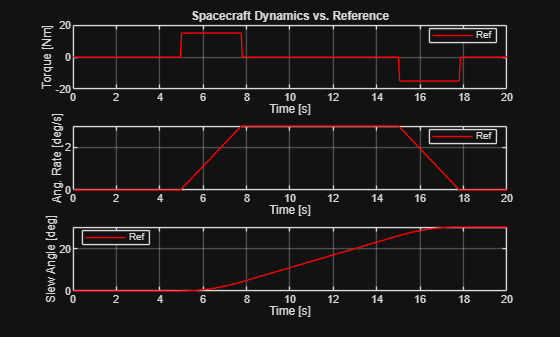

fig1 = figure('Name','Spacecraft Dynamics vs. Reference');
subplot(3,1,1)
plot(timevec,trqCmd,'r','DisplayName','Ref');
title('Spacecraft Dynamics vs. Reference');
xlabel('Time [s]')
ylabel('Torque [Nm]')
legend('location','best');
grid on

subplot(3,1,2)
plot(timevec,satAngRate_deg,'r','DisplayName','Ref');
xlabel('Time [s]');
ylabel('Ang. Rate [deg/s]');
legend('location','best');
grid on

subplot(3,1,3)
plot(timevec,satAtt_deg,'r','DisplayName','Ref');
xlabel('Time [s]');
ylabel('Slew Angle [deg]');
legend('location','best');
grid on

## CMG Steering

% The CMG torque command is the negative of the spacecraft torque command:
cmgTrqCmd = [zeros(size(timevec)), -trqCmd, zeros(size(timevec))];

### Moore-Penrose Pseudoinverse

gimbalRatesMP = zeros(length(timevec),4);
gimbalRatesMPlim = zeros(length(timevec),4);
gimbalAnglesMP = zeros(length(timevec),4);
cmgTrqMP = zeros(length(timevec),3);
cmgAngMomMP = zeros(length(timevec),3);
cmgDetCCtMP = zeros(size(timevec));

gimbalAnglesMP(1,:) = cmgGimbalAngles0';
for ii=1:1:length(timevec)
    cmgPyrState = calcCmgPyrState(gimbalAnglesMP(ii,:)',cmgSkewAngle,cmgFwAngMom);
    cmgAngMomMP(ii,:) = cmgPyrState.hCmg';
    C = cmgPyrState.jacob;
    cmgDetCCtMP(ii) = det(C*C')/cmgFwAngMom^6;
    gimbalRatesMP(ii,:) = (C'*inv(C*C')*cmgTrqCmd(ii,:)')';
    gimbalRatesMPlim(ii,:) = veclim(gimbalRatesMP(ii,:),cmgMaxGimbalRate);
    cmgTrqMP(ii,:) = (C*gimbalRatesMPlim(ii,:)')';

    if ii<length(timevec)
        gimbalAnglesMP(ii+1,:) = gimbalAnglesMP(ii,:) + dt*gimbalRatesMPlim(ii,:);
    end
end

satAngRateMP_deg = dt*cumsum(-cmgTrqMP,1) * (1/satMoi) * 180/pi;
satAttMP_deg = dt*cumsum(satAngRateMP_deg,1);

#### Plot CMG Array Torque

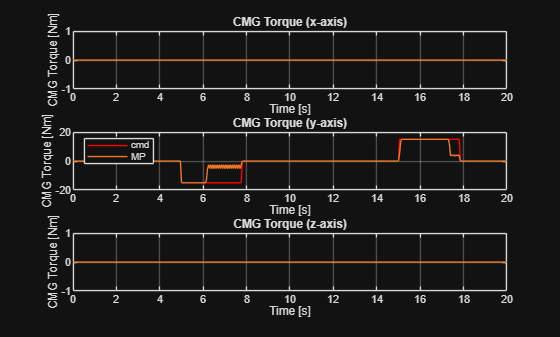

figCmgTrq = figure('Name','CMG Torque');
subplot(3,1,1)
plot(timevec,cmgTrqCmd(:,1),'r','DisplayName','cmd');
hold on
plot(timevec,cmgTrqMP(:,1),'DisplayName','MP');
grid on
xlabel('Time [s]');
ylabel('CMG Torque [Nm]');
title('CMG Torque (x-axis)')

subplot(3,1,2)
plot(timevec,cmgTrqCmd(:,2),'r','DisplayName','cmd');
hold on
plot(timevec,cmgTrqMP(:,2),'DisplayName','MP');
grid on
xlabel('Time [s]');
ylabel('CMG Torque [Nm]');
title('CMG Torque (y-axis)')
legend('Location','northwest');

subplot(3,1,3)
plot(timevec,cmgTrqCmd(:,3),'r','DisplayName','cmd');
hold on
plot(timevec,cmgTrqMP(:,3),'DisplayName','MP');
grid on
xlabel('Time [s]');
ylabel('CMG Torque [Nm]');
title('CMG Torque (z-axis)')

#### Plot CMG Gimbal Rates

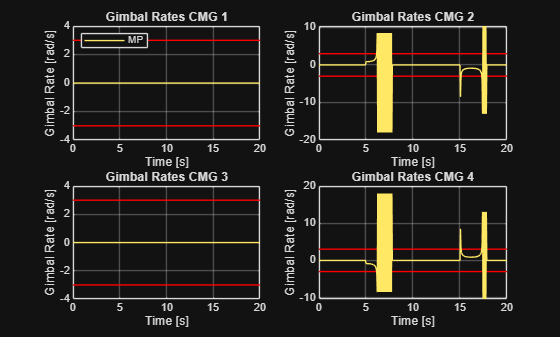

figGr = figure('Name','CMG Gimbal Rates');
subplot(2,2,1)
plot(timevec([1 end]),cmgMaxGimbalRate*[1 1],'r','HandleVisibility','off');
hold on
plot(timevec([1 end]),-cmgMaxGimbalRate*[1 1],'r','HandleVisibility','off');
plot(timevec,gimbalRatesMP(:,1),'DisplayName','MP');
grid on
xlabel('Time [s]');
ylabel('Gimbal Rate [rad/s]');
title('Gimbal Rates CMG 1')
legend('Location','northwest');

subplot(2,2,2)
plot(timevec([1 end]),cmgMaxGimbalRate*[1 1],'r','HandleVisibility','off');
hold on
plot(timevec([1 end]),-cmgMaxGimbalRate*[1 1],'r','HandleVisibility','off');
plot(timevec,gimbalRatesMP(:,2),'DisplayName','MP');
grid on
xlabel('Time [s]');
ylabel('Gimbal Rate [rad/s]');
title('Gimbal Rates CMG 2')

subplot(2,2,3)
plot(timevec([1 end]),cmgMaxGimbalRate*[1 1],'r','HandleVisibility','off');
hold on
plot(timevec([1 end]),-cmgMaxGimbalRate*[1 1],'r','HandleVisibility','off');
plot(timevec,gimbalRatesMP(:,3),'DisplayName','MP');
grid on
xlabel('Time [s]');
ylabel('Gimbal Rate [rad/s]');
title('Gimbal Rates CMG 3')

subplot(2,2,4)
plot(timevec([1 end]),cmgMaxGimbalRate*[1 1],'r','HandleVisibility','off');
hold on
plot(timevec([1 end]),-cmgMaxGimbalRate*[1 1],'r','HandleVisibility','off');
plot(timevec,gimbalRatesMP(:,4),'DisplayName','MP');
grid on
xlabel('Time [s]');
ylabel('Gimbal Rate [rad/s]');
title('Gimbal Rates CMG 4')

#### Plot CMG Gimbal Angles

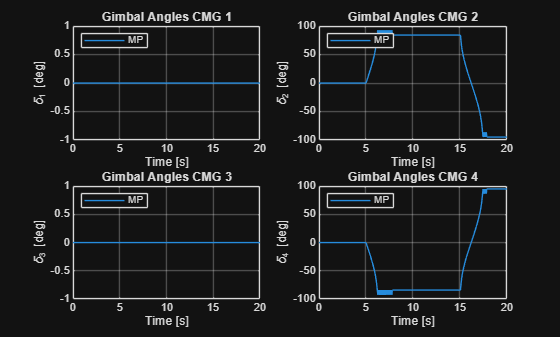

figGa = figure('Name','CMG Gimbal Angles');
subplot(2,2,1)
plot(timevec,180/pi*gimbalAnglesMP(:,1),'DisplayName','MP');
grid on
xlabel('Time [s]');
ylabel('\delta_1 [deg]');
title('Gimbal Angles CMG 1')
legend('Location','northwest');

subplot(2,2,2)
plot(timevec,180/pi*gimbalAnglesMP(:,2),'DisplayName','MP');
grid on
xlabel('Time [s]');
ylabel('\delta_2 [deg]');
title('Gimbal Angles CMG 2')
legend('Location','northwest');

subplot(2,2,3)
plot(timevec,180/pi*gimbalAnglesMP(:,3),'DisplayName','MP');
grid on
xlabel('Time [s]');
ylabel('\delta_3 [deg]');
title('Gimbal Angles CMG 3')
legend('Location','northwest');

subplot(2,2,4)
plot(timevec,180/pi*gimbalAnglesMP(:,4),'DisplayName','MP');
grid on
xlabel('Time [s]');
ylabel('\delta_4 [deg]');
title('Gimbal Angles CMG 4')
legend('Location','northwest');

#### Plot CMG Angular Momentum and Singularity Measure

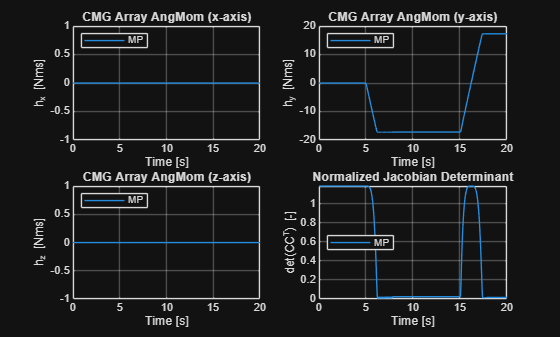

figH = figure('Name','CMG Array Angular Momentum and Singularity Measure');
subplot(2,2,1)
plot(timevec,cmgAngMomMP(:,1),'DisplayName','MP');
grid on
xlabel('Time [s]');
ylabel('h_x [Nms]');
title('CMG Array AngMom (x-axis)')
legend('Location','northwest');

subplot(2,2,2)
plot(timevec,cmgAngMomMP(:,2),'DisplayName','MP');
grid on
xlabel('Time [s]');
ylabel('h_y [Nms]');
title('CMG Array AngMom (y-axis)')
legend('Location','northwest');

subplot(2,2,3)
plot(timevec,cmgAngMomMP(:,3),'DisplayName','MP');
grid on
xlabel('Time [s]');
ylabel('h_z [Nms]');
title('CMG Array AngMom (z-axis)')
legend('Location','northwest');

subplot(2,2,4)
plot(timevec,cmgDetCCtMP,'DisplayName','MP');
xlabel('Time [s]');
ylabel('det(CC^T) [-]');
title('Normalized Jacobian Determinant')
legend('location','west')
grid on

### Local Gradient Steering Law

gimbalRatesLG = zeros(length(timevec),4);
gimbalRatesLGlim = zeros(length(timevec),4);
gimbalAnglesLG = zeros(length(timevec),4);
cmgTrqLG = zeros(length(timevec),3);
cmgAngMomLG = zeros(length(timevec),3);
cmgDetCCtLG = zeros(size(timevec));

gimbalAnglesLG(1,:) = cmgGimbalAngles0';
for ii=1:1:length(timevec)
    cmgPyrState = calcCmgPyrState(gimbalAnglesLG(ii,:)',cmgSkewAngle,cmgFwAngMom);
    cmgAngMomLG(ii,:) = cmgPyrState.hCmg';
    C = cmgPyrState.jacob;
    cmgDetCCtLG(ii) = det(C*C')/cmgFwAngMom^6;
    gimbalRatesLG(ii,:) = (pinv(C)*cmgTrqCmd(ii,:)')';
    gimbalRatesLGlim(ii,:) = veclim(gimbalRatesLG(ii,:),cmgMaxGimbalRate);
    cmgTrqLG(ii,:) = (C*gimbalRatesLGlim(ii,:)')';

    if ii<length(timevec)
        gimbalAnglesLG(ii+1,:) = gimbalAnglesLG(ii,:) + dt*gimbalRatesLGlim(ii,:);
    end
end

satAngRateLG_deg = dt*cumsum(-cmgTrqLG,1) * (1/satMoi) * 180/pi;
satAttLG_deg = dt*cumsum(satAngRateLG_deg,1);

#### Plot CMG Array Torque

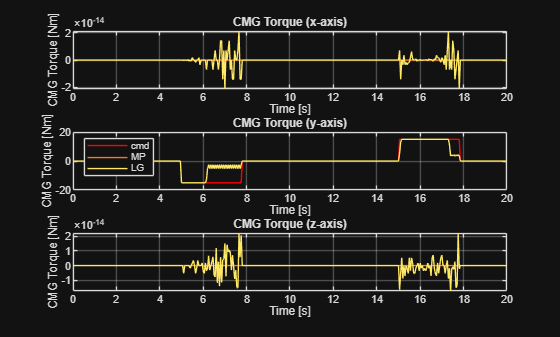

figure(figCmgTrq);
subplot(3,1,1)
if ~ishold;hold on;end
plot(timevec,cmgTrqLG(:,1),'DisplayName','LG');

subplot(3,1,2)
if ~ishold;hold on;end
plot(timevec,cmgTrqLG(:,2),'DisplayName','LG');

subplot(3,1,3)
if ~ishold;hold on;end
plot(timevec,cmgTrqLG(:,3),'DisplayName','LG');

#### Plot CMG Gimbal Rates

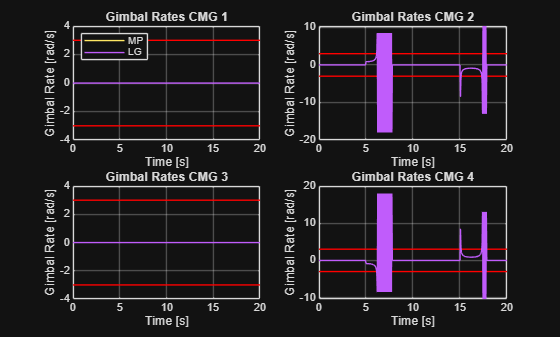

figure(figGr);
subplot(2,2,1)
if ~ishold;hold on;end
plot(timevec,gimbalRatesLG(:,1),'DisplayName','LG');

subplot(2,2,2)
if ~ishold;hold on;end
plot(timevec,gimbalRatesLG(:,2),'DisplayName','LG');

subplot(2,2,3)
if ~ishold;hold on;end
plot(timevec,gimbalRatesLG(:,3),'DisplayName','LG');

subplot(2,2,4)
if ~ishold;hold on;end
plot(timevec,gimbalRatesLG(:,4),'DisplayName','LG');

#### Plot CMG Gimbal Angles

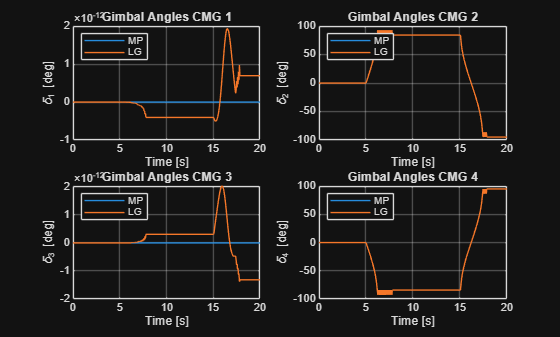

figure(figGa);
subplot(2,2,1)
if ~ishold;hold on;end
plot(timevec,180/pi*gimbalAnglesLG(:,1),'DisplayName','LG');

subplot(2,2,2)
if ~ishold;hold on;end
plot(timevec,180/pi*gimbalAnglesLG(:,2),'DisplayName','LG');

subplot(2,2,3)
if ~ishold;hold on;end
plot(timevec,180/pi*gimbalAnglesLG(:,3),'DisplayName','LG');

subplot(2,2,4)
if ~ishold;hold on;end
plot(timevec,180/pi*gimbalAnglesLG(:,4),'DisplayName','LG');

#### Plot CMG Singularity Measure

figDet = figure('Name','CMG Singularity Measure');
figure(figDet);
if ~ishold;hold on;end
plot(timevec,cmgDetCCtLG,'DisplayName','LG');

### Generalized Singularity-Robust Inverse

gimbalRatesGSR = zeros(length(timevec),4);
gimbalRatesGSRlim = zeros(length(timevec),4);
gimbalAnglesGSR = zeros(length(timevec),4);
cmgTrqGSR = zeros(length(timevec),3);
cmgAngMomGSR = zeros(length(timevec),3);
cmgDetCCtGSR = zeros(size(timevec));

gimbalAnglesGSR(1,:) = cmgGimbalAngles0';
for ii=1:1:length(timevec)
    cmgPyrState = calcCmgPyrState(gimbalAnglesGSR(ii,:)',cmgSkewAngle,cmgFwAngMom);
    cmgAngMomGSR(ii,:) = cmgPyrState.hCmg';
    C = cmgPyrState.jacob;
    cmgDetCCtGSR(ii) = det(C*C')/cmgFwAngMom^6;
    gsrPars.t = timevec(ii);
    gimbalRatesGSR(ii,:) = cmgSteeringGsr(C,cmgTrqCmd(ii,:)',cmgFwAngMom,gsrPars);
    gimbalRatesGSRlim(ii,:) = veclim(gimbalRatesGSR(ii,:),cmgMaxGimbalRate);
    cmgTrqGSR(ii,:) = (C*gimbalRatesGSRlim(ii,:)')';

    if ii<length(timevec)
        gimbalAnglesGSR(ii+1,:) = gimbalAnglesGSR(ii,:) + dt*gimbalRatesGSRlim(ii,:);
    end
end

satAngRateGSR_deg = dt*cumsum(-cmgTrqGSR,1) * (1/satMoi) * 180/pi;
satAttGSR_deg = dt*cumsum(satAngRateGSR_deg,1);

#### Plot CMG Array Torque

figure(figCmgTrq);
subplot(3,1,1)
if ~ishold;hold on;end
plot(timevec,cmgTrqGSR(:,1),'DisplayName','GSR');

subplot(3,1,2)
if ~ishold;hold on;end
plot(timevec,cmgTrqGSR(:,2),'DisplayName','GSR');

subplot(3,1,3)
if ~ishold;hold on;end
plot(timevec,cmgTrqGSR(:,3),'DisplayName','GSR');

#### Plot CMG Gimbal Rates

figure(figGr);
subplot(2,2,1)
if ~ishold;hold on;end
plot(timevec,gimbalRatesGSR(:,1),'DisplayName','GSR');

subplot(2,2,2)
if ~ishold;hold on;end
plot(timevec,gimbalRatesGSR(:,2),'DisplayName','GSR');

subplot(2,2,3)
if ~ishold;hold on;end
plot(timevec,gimbalRatesGSR(:,3),'DisplayName','GSR');

subplot(2,2,4)
if ~ishold;hold on;end
plot(timevec,gimbalRatesGSR(:,4),'DisplayName','GSR');

#### Plot CMG Gimbal Angles

figure(figGa);
subplot(2,2,1)
if ~ishold;hold on;end
plot(timevec,180/pi*gimbalAnglesGSR(:,1),'DisplayName','GSR');

subplot(2,2,2)
if ~ishold;hold on;end
plot(timevec,180/pi*gimbalAnglesGSR(:,2),'DisplayName','GSR');

subplot(2,2,3)
if ~ishold;hold on;end
plot(timevec,180/pi*gimbalAnglesGSR(:,3),'DisplayName','GSR');

subplot(2,2,4)
if ~ishold;hold on;end
plot(timevec,180/pi*gimbalAnglesGSR(:,4),'DisplayName','GSR');

#### Plot CMG Array Angular Momentum and Singularity Measure

figure(figH);
subplot(2,2,1)
if ~ishold;hold on;end
plot(timevec,cmgAngMomGSR(:,1),'DisplayName','GSR');
legend('location','best')

subplot(2,2,2)
if ~ishold;hold on;end
plot(timevec,cmgAngMomGSR(:,2),'DisplayName','GSR');
legend('location','best')

subplot(2,2,3)
if ~ishold;hold on;end
plot(timevec,cmgAngMomGSR(:,3),'DisplayName','GSR');
legend('location','best')

subplot(2,2,4)
if ~ishold;hold on;end
plot(timevec,cmgDetCCtGSR,'DisplayName','GSR');
legend('location','best')